# Denoise PPG Using Deep Learning Networks

## Plot noisy PPG and clean PPG

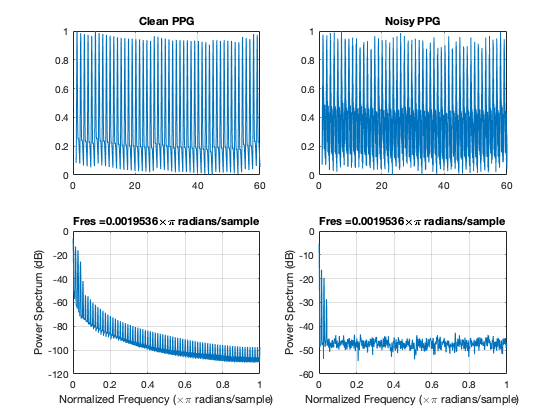


subplot(221)
plot(signal_PPG(1).x_minute,signal_PPG(1).normal.syntheticPPG)
title("Clean PPG")
grid on
subplot(222)
xlabel("Time (s)")
plot(signal_PPG(1).x_minute,signal_PPG(1).noise.syntheticPPG)
title("Noisy PPG")
grid on

% Compute power spectrum
frequencyLimits = [0 1]*pi; % Normalized frequency (rad/sample)
%%
% Index into signal time region of interest
timeLimits = [1 signal_PPG(1).data_points]; % samples
signal_test_ROI = signal_PPG(1).normal.syntheticPPG;
signal_test_ROI = signal_test_ROI(timeLimits(1):timeLimits(2));
subplot(223)
% Compute spectral estimate
% Run the function call below without output arguments to plot the results
pspectrum(signal_test_ROI, ...
    'FrequencyLimits',frequencyLimits);

% Index into signal time region of interest
signal_test_ROI = signal_PPG(1).noise.syntheticPPG;
signal_test_ROI = signal_test_ROI(timeLimits(1):timeLimits(2));
subplot(224)
% Compute spectral estimate
% Run the function call below without output arguments to plot the results
pspectrum(signal_test_ROI, ...
    'FrequencyLimits',frequencyLimits);

## Generate network image input data

#### The parameters needed to do the spectrograms

clear all;
load('Signal.mat', 'signal_PPG');

WindowLength = 140;
win          = hamming(WindowLength,"periodic");
Overlap      = round(0.50 * WindowLength);
FFTLength    = WindowLength;
NumFeatures  = FFTLength/2 + 1;
NumSegments  = 8;
Fs           = signal_PPG(1).samplin_frequency;


#### Step 1: Calculate the spectrograms---- PARA TODO EL DATA SET IR DIRECTAMENTE AL PASO 3

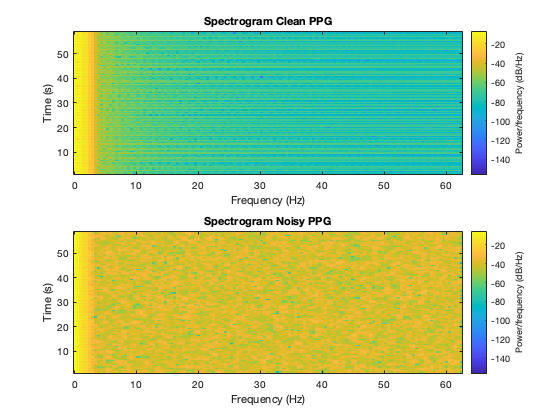

STFT_PPG = struct;

STFT_PPG(1).normal.syntheticPPG = spectrogram(signal_PPG(1).normal.syntheticPPG, win, Overlap, FFTLength, Fs); 
STFT_PPG(1).normal.syntheticPPG_abs = abs(STFT_PPG(1).normal.syntheticPPG);

STFT_PPG(1).noise.syntheticPPG = spectrogram(signal_PPG(1).noise.syntheticPPG, win, Overlap, FFTLength,Fs);
STFT_PPG(1).noise.syntheticPPG_abs  = abs(STFT_PPG(1).noise.syntheticPPG );

figure
subplot(211)
spectrogram(signal_PPG(1).normal.syntheticPPG, win, Overlap, FFTLength, Fs)
title("Spectrogram Clean PPG")
subplot(212)
spectrogram(signal_PPG(1).noise.syntheticPPG, win, Overlap, FFTLength,Fs)
title("Spectrogram Noisy PPG")

#### Step 2: Generate 8-segment training predictor signals

We create 8 copies of the spectrogram that we shift by one spectrogram-time step for each. Now we have our Predictors and Targets. 

STFT_PPG(1).noise.syntheticPPG_abs = [STFT_PPG(1).noise.syntheticPPG_abs(:,1:NumSegments-1) STFT_PPG(1).noise.syntheticPPG_abs];

STFT_PPG(1).normal.syntheticPPG_abs = [STFT_PPG(1).normal.syntheticPPG_abs(:,1:NumSegments-1) STFT_PPG(1).normal.syntheticPPG_abs];


for index = 1:size(STFT_PPG(1).noise.syntheticPPG_abs,2) - NumSegments + 1
    STFT_PPG(1).noise.STFTSegments(:,:,index) = (STFT_PPG(1).noise.syntheticPPG_abs(:,index:index+NumSegments-1)); 
end

STFT_PPG(1).targets   = STFT_PPG(1).normal.syntheticPPG_abs;
size(STFT_PPG(1).targets)

ans =    129   114


STFT_PPG(1).predictors = STFT_PPG(1).noise.STFTSegments;
size(STFT_PPG(1).predictors)

ans =    129     8   114


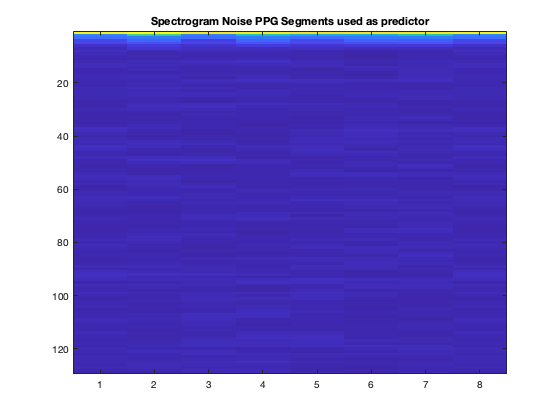


figure, imagesc(STFT_PPG(1).predictors(:,:,1))
title("Spectrogram Noise PPG Segments used as predictor")

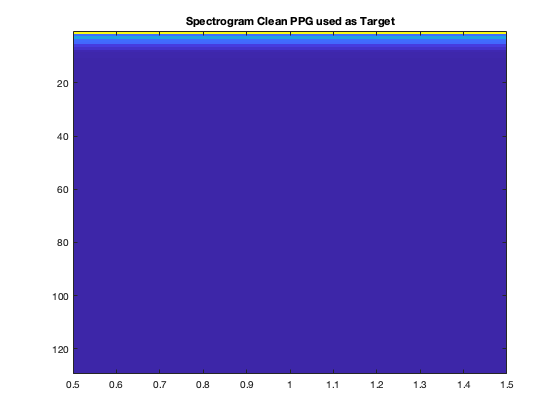

figure, imagesc(STFT_PPG(1).targets(:,1))
title("Spectrogram Clean PPG used as Target")

#### Step 3: Generate for all data

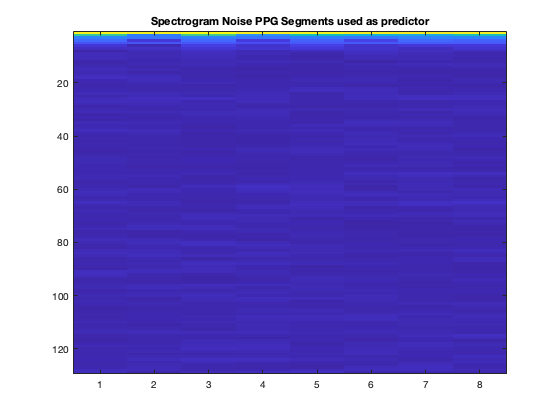

STFT_PPG = struct;
for i=1:88
    
STFT_PPG(i).normal.syntheticPPG = spectrogram(signal_PPG(i).normal.syntheticPPG, win, Overlap, FFTLength, Fs); 
STFT_PPG(i).normal.syntheticPPG_abs = abs(STFT_PPG(i).normal.syntheticPPG);

STFT_PPG(i).noise.syntheticPPG = spectrogram(signal_PPG(i).noise.syntheticPPG, win, Overlap, FFTLength,Fs);
STFT_PPG(i).noise.syntheticPPG_abs  = abs(STFT_PPG(i).noise.syntheticPPG );

STFT_PPG(i).noise.syntheticPPG_abs = [STFT_PPG(i).noise.syntheticPPG_abs(:,1:NumSegments-1) STFT_PPG(i).noise.syntheticPPG_abs ];

for index = 1:size(STFT_PPG(i).noise.syntheticPPG_abs,2) - NumSegments + 1
    STFT_PPG(i).noise.STFTSegments(:,:,index) = (STFT_PPG(i).noise.syntheticPPG_abs(:,index:index+NumSegments-1)); 
end

STFT_PPG(i).targets   = STFT_PPG(i).normal.syntheticPPG_abs;
STFT_PPG(i).predictors = STFT_PPG(i).noise.STFTSegments;  
    
end

% TEST DATA SET ALANIZAR LA TERCERA DIMENSION DE PREDICTORS
T=12;
figure, imagesc(STFT_PPG(T).predictors(:,:,9))
title("Spectrogram Noise PPG Segments used as predictor")

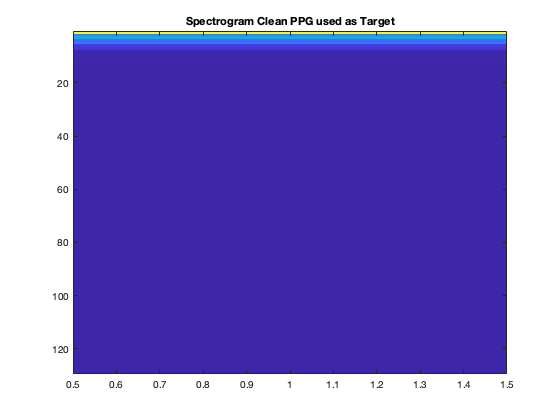

figure, imagesc(STFT_PPG(T).targets(:,1))
title("Spectrogram Clean PPG used as Target")

## Split into Training and Validation data

You will use 1% of the data for validation during training. Validation is useful to detect scenarios where the network is overfitting the training data.

Randomly split the data into training and validation sets.

%predictors = STFT_PPG.predictors;
%targets = STFT_PPG.targets;

for i=1:size(STFT_PPG,2)
    predictors(:,:,:,i) = STFT_PPG(i).predictors;
end

for i=1:size(STFT_PPG,2)
    targets(:,:,i) = STFT_PPG(i).targets;
end

% concatenate data in 3D
predictors = reshape(predictors,[size(predictors,1),size(predictors,2),size(predictors,3)*size(predictors,4)]);
targets = reshape(targets,[size(targets,1),size(targets,2)*size(targets,3)]);


% Transform data to 4D
predictors  = reshape(predictors,size(predictors,1),size(predictors,2),1,size(predictors,3));
targets     = reshape(targets,1,1,size(targets,1),size(targets,2));


inds                = randperm(size(predictors,4));
L                   = round(0.80 * size(predictors,4));
trainPredictors     = predictors(:,:,:,inds(1:L));
trainTargets        = targets(:,:,:,inds(1:L));
validatePredictors  = predictors(:,:,:,inds(L+1:end));
validateTargets     = targets(:,:,:,inds(L+1:end));


## PPG Denoising with Convolutional Layers

Fully convolutional network comprising 16 convolutional layers. The first 15 convolutional layers are groups of 3 layers, repeated 5 times, with filter widths of 9, 5, and 9, and number of filters of 18, 30 and 8, respectively. The last convolutional layer has a filter width of 129 and 1 filter. In this network, convolutions are performed in only one direction (along the frequency dimension), and the filter width along the time dimension is set to 1 for all layers expect the first one. 

layers = [imageInputLayer([NumFeatures,NumSegments])
%           imageInputLayer([129,8,114])
          convolution2dLayer([9 8],18,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          repmat(...
          [convolution2dLayer([5 1],30,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([9 1],8,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([9 1],18,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer], 4,1) % repeat this sequence 4 times
          
          convolution2dLayer([5 1],30,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([9 1],8,"Stride",[1 100],"Padding","same")
          batchNormalizationLayer
          reluLayer
          
          convolution2dLayer([129 1],1,"Stride",[1 100],"Padding","same")
          
          regressionLayer
          ]

layers =   48×1 Layer array with layers:

     1   ''   Image Input           129×8×1 images with 'zerocenter' normalization
     2   ''   Convolution           18 9×8 convolutions with stride [1  100] and padding 'same'
     3   ''   Batch Normalization   Batch normalization
     4   ''   ReLU                  ReLU
     5   ''   Convolution           30 5×1 convolutions with stride [1  100] and padding 'same'
     6   ''   Batch Normalization   Batch normalization
     7   ''   ReLU                  ReLU
     8   ''   Convolution           8 9×1 convolutions with stride [1  100] and padding 'same'
     9   ''   Batch Normalization   Batch normalization
    10   ''   ReLU                  ReLU
    11   ''   Convolution           18 9×1 convolutions with stride [1  100] and padding 'same'
    12   ''   Batch Normalization   Batch normalization
    13   ''   ReLU                  ReLU
    14   ''   Convolution  

## Training options

miniBatchSize = 32;
options = trainingOptions("adam", ...
    "MaxEpochs",20, ...
    "InitialLearnRate",1e-5,...
    "MiniBatchSize",miniBatchSize, ...
    "Shuffle","every-epoch", ...
    "Plots","training-progress", ...
    "Verbose",false, ...
    "ValidationPatience",Inf,...
    "ValidationFrequency",floor(size(trainPredictors,4)/miniBatchSize),...
    "LearnRateSchedule","piecewise",...
    "LearnRateDropFactor",0.9,...
    "LearnRateDropPeriod",1,...
    "ValidationData",{validatePredictors,permute(validateTargets,[3 1 2 4])});

## Train network

Train the network with the specified training options and layer architecture using `trainNetwork`. Because the training set is large, the training process can take several minutes. 

denoiseNetFullyConvolutional = trainNetwork(trainPredictors,permute(trainTargets,[3 1 2 4]),layers,options);

## Test the Denoising Networks

Use PPG signals 

STFTFullyConvolutional = predict(denoiseNetFullyConvolutional, predictors);
% Scale the outputs by the mean and standard deviation used in the training stage.
STFTFullyConvolutional(:) = cleanStd * STFTFullyConvolutional(:) +  cleanMean;

Unrecognized function or variable 'cleanStd'.


%% Use spectrogram to generate magnitude STFT vectors from the noisy audio signals:
noisySTFT  = spectrogram(noisyAudio, win, Overlap, FFTLength,Fs);
noisyPhase = angle(predictors);
noisySTFT  = abs(predictors);
%% Compute the denoised speech signals. istft performs the inverse STFT. Use the phase of the noisy STFT vectors to reconstruct the time-domain signal.
denoisedAudio = istft(squeeze(STFTFullyConvolutional) .* exp(1j*noisyPhase), ...
    WindowLength-Overlap, FFTLength, win);